# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_vfi_sgml.mlx
    ----------------
    This code solves the stochastic growth model with endogenous labor supply using value function iteration.

%}

## Model: Stochastic Growth Model with Endogenous Labor.

The social planner's problem is


$$\underset{\{c_t\}_{t=1}^{\infty},\{n_t\}_{t=1}^{\infty},\{k_{t+1}\}_{t=1}^{\infty}}{\text{max }} \mathbb{E}_0\sum_{t=1}^\infty \beta^{t} \left[\frac{c_t^{1-\sigma}}{1-\sigma} + \gamma\frac{(1-n_t)^{1+\frac{1}{\nu}}}{1+\frac{1}{\nu}} \right] \text{ ,}$$


 
$$\begin{array}{r l} \text{s.t. } y_t = c_t+i_t \end{array} \ ,$$


 
$$\begin{array}{r l} y_t = A_t k_t^{\alpha}n_t^{1-\alpha} \end{array} \ ,$$


 
$$\begin{array}{r l} k_{t+1} = (1-\delta)k_t+ i_t \end{array} \ ,$$


 
$$\begin{array}{r l} \text{log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$


 
$$\begin{array}{r l} 1 = n_t + l_t \end{array} \ ,$$



$$c_t > 0,  k_t > 0 \ ,$$


where $|\rho| < 1$, $\epsilon_{t+1}\sim\mathcal{N}(0,\sigma^2_{\epsilon})$, and the constraints are for $t = 1, 2, ...,$. The rationale for the constraints that are similar to those in the stochastic growth model. The second to the last line is the time constraint: given an endowment of one unit of time, part of it can go to labor $n_t$ and the rest will go to leisure $l_t$. Consumers derive utility from leisure but must supply labor to produce the final good. The choice of utility functions for consumption and leisure are assumptions based on the literature; other functions exist and will be discussed when discussing households in greater detail.

## Recursive Formulation.

The recursive formulation, combining the constraints into one, is


$$V_t(k_t,A_t) = \underset{c_t, n_t, k_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \gamma\frac{(1-n_t)^{1+\frac{1}{\nu}}}{1+\frac{1}{\nu}} + \beta \mathbb{E}_t\left[V_{t+1}(k_{t+1},A_{t+1})\right] \ ,$$


 
$$\begin{array}{r l} \text{s.t. } A_tk_t^{\alpha}n_t^{1-\alpha} =  c_t + k_{t+1} - (1-\delta)k_t\end{array} \ \text{for} \ t = 1, 2, ... \ ,$$


 
$$\begin{array}{r l} \text{log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$


 
$$\begin{array}{r l} 1 = n_t + l_t \end{array} \ ,$$



$$c_t > 0,  k_t > 0 \text{ .}$$


Because of the labor supply choice, the choice space has now expanded to include this. Substituting the combined constraint into the utility function gives


$$V_t(k_t,A_t) = \underset{n_t,k_{t+1}}{\text{max}}\frac{\left(A_tk_t^{\alpha}n_t^{1-\alpha}+(1-\delta)k_t-k_{t+1}\right)^{1-\sigma}}{1-\sigma} + \gamma\frac{(1-n_t)^{1+\frac{1}{\nu}}}{1+\frac{1}{\nu}} + \beta \mathbb{E}_t\left[V_{t+1}(k_{t+1},A_{t+1})\right] \ ,$$


 
$$\begin{array}{r l} \text{s.t. log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$


 
$$\begin{array}{r l} 1 = n_t + l_t \end{array} \ ,$$



$$k_t > 0 \ ,$$


simplifying the problem slightly.

## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('/Users/hanhnguyen/Documents/MATLAB/Matlab'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is /Users/hanhnguyen/Documents/MATLAB/Matlab 



## Set the parameters and generate the state space.

Calls: model.m.

As before, we cannot directly compute the steady state capital because of the productivity fluctuations, but we can still build the grid for $k_t$ around the deterministic steady state.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Value Function Iteration.

Calls: solve.m, and model.m.

Note that the allocation of labor and leisure is a static decision. From (5.23) in Adda and Cooper, the intratemporal condition is


$$(A_tk_t^{\alpha}n_t^{1-\alpha}+(1-\delta)k_{t}-k_{t+1})^{-\sigma}A_t(1-\alpha)k_t^{\alpha}n_t^{-\alpha} = -\gamma(1-n_t)^{\frac{1}{\nu}} \ .$$


We have pre-determined grids for $k_t$ and $A_t$, and we use the same grid for $k_{t+1}$ as $k_t$. Given these and the equation above, we can $n_t$ by using a numerical solver to minimize


$$f(n_t) = (A_tk_t^{\alpha}n_t^{1-\alpha}+(1-\delta)k_{t}-k_{t+1})^{-\sigma}A_t(1-\alpha)k_t^{\alpha}n_t^{-\alpha} + \gamma(1-n_t)^{\frac{1}{\nu}} \ ,$$


and obtain optimal labor supply given any combination of the state variables and any potential choice of $k_{t+1}$ associated with these. Crucially, we can do this outside of the value function iteration algorithm because the decision is static. Once we have the optimal $n_t$, we can treat this as a parameter for each combination of $k_t, k_{t+1},$ and $A_t$.

t = cputime;
sol = solve.grow(par); % Solve the model using Value Function Iteration.

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.

Converged in 277 iterations.

------------End of Value Function Iteration.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 14.4100 seconds.


## Simulate the model and plot the model functions and time series.

Calls: simulate.m and my_graph.m.

The model functions behave in a similarly to those in the stochastic growth model. The difference now is that labor supply is negatively correlated with productivity. This is because when $A_t$ is low, labor supply increases to boost output; when $A_t$ is high, less labor is needed to produce a given level of output and more time can be spent on leisure. Given a Cobb-Douglas production function with constant returns to scale, the marginal product of labor is increasing with capital so $n_t$ increases with $k_t$.

The time series data have similar qualitative results as in the model without labor supply. Labor itself is relatively constant (see the units of the graph). 

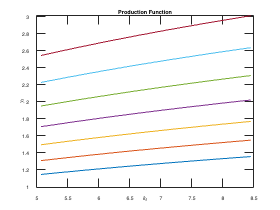

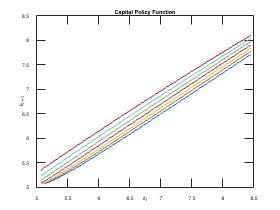

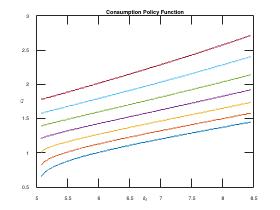

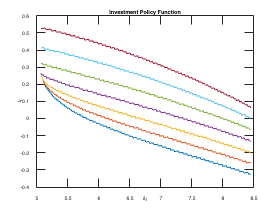

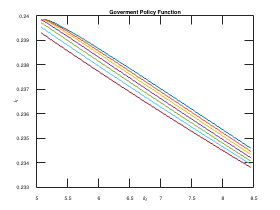

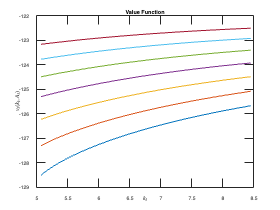

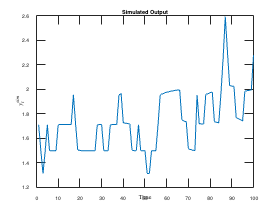

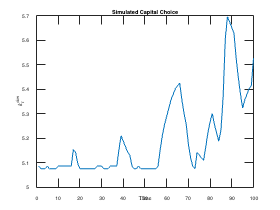

sim = simulate.grow(par,sol); % Simulate the model.
my_graph.plot_policy(par,sol,sim,figout) % Plot the model functions and time series.

## Analysis.

To check the validity of the model, we compute statistics of interest and see how the data line up. In some cases, these are explicitly targeted by adjusting or estimating parameters that govern the behavior of the simulated data. In our case, we just set these exogenously from the literature, which in turn obtain these from data or estimation. The model differs from the literature so this model is off from the data, see Table 5.1 in Adda and Cooper.

% Compute the variables corresponding to data. The model assumes the data are detrended.

ysim = sim.ysim; % Output.
ksim = sim.ksim; % Capital Stock.

isim = sim.isim; % Investment.
csim = sim.csim; % Consumption.
w = (1-par.alpha).*sim.Asim.*ksim.^(par.alpha); % Wages = MPL.

% Std. Dev of variables relative to output.

cvar = sqrt(var(csim))/sqrt(var(ysim));
ivar = sqrt(var(isim))/sqrt(var(ysim));

wvar = sqrt(var(w))/sqrt(var(ysim));

fprintf('The Std. Dev of Consumption Relative to Output is: %0.4f',cvar)

The Std. Dev of Consumption Relative to Output is: 0.8703

fprintf('The Std. Dev of Investment Relative to Output is: %0.4f',ivar)

The Std. Dev of Investment Relative to Output is: 0.1909


fprintf('The Std. Dev of Real Wages Relative to Output is: %0.4f',wvar)

The Std. Dev of Real Wages Relative to Output is: 0.6810

## Comparision

filename = 'dataps5.xlsx'; 
data = readtable(filename);

disp(data)

    VietNam    LabourForceAt15YearsOfAgeAndAboveByProvince___ByCities_Provinci    NumberOfNewlyEstablishedEnterprisesByProvinceByCities_Provincie       GDP        FDI_NetInflows_BoP_CurrentUS__    GDPPerPersonEmployed    GDPGrowthRate    consumption    invesment_capita
    _______    _______________________________________________________________    _______________________________________________________________    __________    ______________________________    ____________________    _____________    ___________    ________________

     1996                                     NaN                                                                NaN                                 2.46

% Extract all data points
Asim_all = sim.Asim;
ysim_all = sim.ysim;
ksim_all = sim.ksim;
csim_all = sim.csim;
gsim_all = sim.gsim;
isim_all = sim.isim;
usim_all = sim.usim;


% Extract and compute log for all data points
log_GDP_per_worker = log(data.GDPPerPersonEmployed);
log_Consumption = log(data.consumption);
log_Investment_per_capita = log(data.invesment_capita);

% Find the minimum length across all vectors
min_length = min([length(data.VietNam), length(log_GDP_per_worker), ...
                  length(ysim_all), length(log_Consumption), ...
                  length(csim_all), length(log_Investment_per_capita), ...
                  length(isim_all)]);

% Trim all vectors to the same length
years = years(1:min_length);
log_GDP_per_worker = log_GDP_per_worker(1:min_length);
ysim_all = ysim_all(1:min_length);
log_Consumption = log_Consumption(1:min_length);
csim_all = csim_all(1:min_length);
log_Investment_per_capita = log_Investment_per_capita(1:min_length);
isim_all = isim_all(1:min_length);

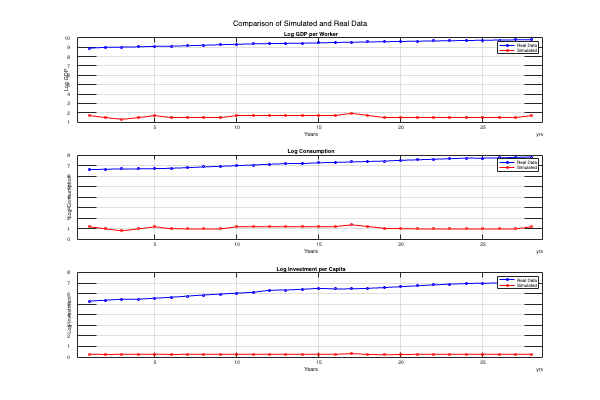

% Create figure
figure('Position', [100, 100, 1200, 800]); 

% Subplot 1: Log GDP per Worker
subplot(3,1,1)
plot(years, log_GDP_per_worker, '-ob', 'LineWidth', 2, 'MarkerSize', 4, 'DisplayName', 'Real Data');
hold on;
plot(years, ysim_all, '-sr', 'LineWidth', 2, 'MarkerSize', 4, 'DisplayName', 'Simulated');
title('Log GDP per Worker');
xlabel('Years');
ylabel('Log GDP');
grid on;
legend;

% Subplot 2: Log Consumption
subplot(3,1,2)
plot(years, log_Consumption, '-ob', 'LineWidth', 2, 'MarkerSize', 4, 'DisplayName', 'Real Data');
hold on;
plot(years, csim_all, '-sr', 'LineWidth', 2, 'MarkerSize', 4, 'DisplayName', 'Simulated');
title('Log Consumption');
xlabel('Years');
ylabel('Log Consumption');
grid on;
legend;

% Subplot 3: Log Investment per Capita
subplot(3,1,3)
plot(years, log_Investment_per_capita, '-ob', 'LineWidth', 2, 'MarkerSize', 4, 'DisplayName', 'Real Data');
hold on;
plot(years, isim_all, '-sr', 'LineWidth', 2, 'MarkerSize', 4, 'DisplayName', 'Simulated');
title('Log Investment per Capita');
xlabel('Years');
ylabel('Log Investment');
legend;
grid on;

% Add overall title
sgtitle('Comparison of Simulated and Real Data');

% Danh sách biến và tên hiển thị
real_data_vars = {log_GDP_per_worker, log_Consumption, log_Investment_per_capita};
sim_data_vars = {ysim_all, csim_all, isim_all};
var_names = {'Log GDP per Worker', 'Log Consumption', 'Log Investment per Capita'};

% Số lượng biến
num_vars = length(real_data_vars);

% Khởi tạo bảng thống kê
stats_table = cell(2*num_vars + 1, 6);
stats_table(1, 2:end) = {'Min', 'Max', 'Mean', 'Median', 'StdDev'}; % Header cột

% Tính toán thống kê
row_idx = 2;
for i = 1:num_vars
    % Real data
    stats_table{row_idx, 1} = [var_names{i}, ' (Real)'];
    data = real_data_vars{i};
    if isempty(data) || all(isnan(data))
        stats_table(row_idx, 2:end) = {'N/A', 'N/A', 'N/A', 'N/A', 'N/A'};
    else
        stats_table(row_idx, 2:end) = {min(data), max(data), mean(data), median(data), std(data)};
    end
    row_idx = row_idx + 1;

    % Simulated data
    stats_table{row_idx, 1} = [var_names{i}, ' (Simulated)'];
    data = sim_data_vars{i};
    if isempty(data) || all(isnan(data))
        stats_table(row_idx, 2:end) = {'N/A', 'N/A', 'N/A', 'N/A', 'N/A'};
    else
        stats_table(row_idx, 2:end) = {min(data), max(data), mean(data), median(data), std(data)};
    end
    row_idx = row_idx + 1;
end

% Hiển thị bảng
disp('Descriptive Statistics Table: Real vs Simulated Data');

Descriptive Statistics Table: Real vs Simulated Data


disp(stats_table);

    {0×0 double                             }    {'Min'   }    {'Max'   }    {'Mean'  }    {'Median'}    {'StdDev'}
    {'Log GDP per Worker (Real)'            }    {[8.8987]}    {[9.7996]}    {[9.4111]}    {[9.4389]}    {[0.2719]}
    {'Log GDP per Worker (Simulated)'       }    {[1.3102]}    {[1.9534]}    {[1.5906]}    {[1.4981]}    {[0.1360]}
    {'Log Consumption (Real)'               }    {[6.6109]}    {[7.8085]}    {[7.2125]}    {[7.2290]}    {[0.3951]}
    {'Log Consumption (Simulated)'          }    {[0.8167]}    {[1.3916]}    {[1.0962]}    {[1.0207]}    {[0.1266]}
    {'Log Investment per Capita (Real)'     }    {[5.2917]}    {[7.0949]}    {[6.2990]}    {[6.4266]}    {[0.5655]}
    {'Log Investment per Capita (Simulated)'}    {[0.2118]}    {[0.3222]}    {[0.2546]}    {[0.2537]}    {[0.0169]}




disp(stats_table);

    {0×0 double                             }    {'Min'   }    {'Max'   }    {'Mean'  }    {'Median'}    {'StdDev'}
    {'Log GDP per Worker (Real)'            }    {[8.8987]}    {[9.7996]}    {[9.4111]}    {[9.4389]}    {[0.2719]}
    {'Log GDP per Worker (Simulated)'       }    {[1.3102]}    {[1.9534]}    {[1.5906]}    {[1.4981]}    {[0.1360]}
    {'Log Consumption (Real)'               }    {[6.6109]}    {[7.8085]}    {[7.2125]}    {[7.2290]}    {[0.3951]}
    {'Log Consumption (Simulated)'          }    {[0.8167]}    {[1.3916]}    {[1.0962]}    {[1.0207]}    {[0.1266]}
    {'Log Investment per Capita (Real)'     }    {[5.2917]}    {[7.0949]}    {[6.2990]}    {[6.4266]}    {[0.5655]}
    {'Log Investment per Capita (Simulated)'}    {[0.2118]}    {[0.3222]}    {[0.2546]}    {[0.2537]}    {[0.0169]}



% Define different values of tau_k for counterfactual analysis $
tau_k_values = [0.1, 0.2, 0.25];

% Initialize storage for results
sim_policies = cell(length(tau_k_values), 5); % Columns for different simulated variables 
par_T = 100; % Giả sử T = 100, nếu par.T không tồn tại

% Run counterfactual analysis for each tau_k
for i = 1:length(tau_k_values)
    % Set up parameters and modify tau_k
    par = model.setup();  
    par.tau_k = tau_k_values(i);  
    
    % Generate grids and solve the model
    par = model.gen_grids(par);
    sol = solve.grow(par);
    
    % Simulate the model
    sim = simulate.grow(par, sol);
    
    % Check par.T to avoid errors
    if isfield(par, 'T')
        par_T = par.T;
    end
    
    % Store all simulated variables, ensure non-empty values
    sim_policies{i, 1} = fillmissing(sim.csim, 'constant', NaN);  % Consumption
    sim_policies{i, 2} = fillmissing(sim.ksim, 'constant', NaN);  % Capital choice
    sim_policies{i, 3} = fillmissing(sim.ysim, 'constant', NaN);  % Output
    sim_policies{i, 4} = fillmissing(sim.isim, 'constant', NaN);  % Investment
    sim_policies{i, 5} = fillmissing(sim.gsim, 'constant', NaN);  % Government spending
end

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.

Converged in 321 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.

Converged in 277 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.

Converged in 244 iterations.

------------End of Value Function Iteration.------------


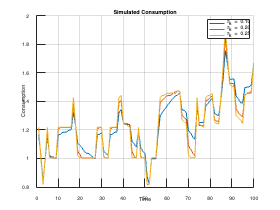

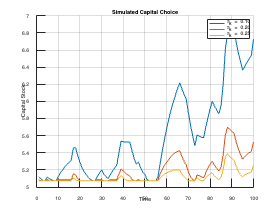

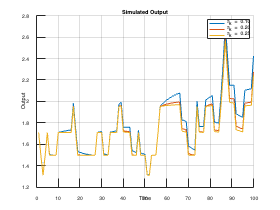

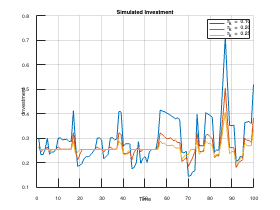

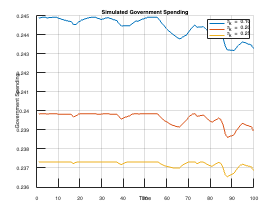

% Define plot labels and titles
plot_vars = {'Consumption', 'Capital Choice', 'Output', 'Investment', 'Government Spending'};
plot_titles = {'Simulated Consumption', 'Simulated Capital Choice', 'Simulated Output', 'Simulated Investment', 'Simulated Government Spending'};
y_labels = {'Consumption', 'Capital Stock', 'Output', 'Investment', 'Government Spending'};

% Create one graph for each simulated variable, showing different tau_k as separate lines
for var_idx = 1:5
    figure;
    hold on;
    colors = lines(length(tau_k_values)); % Generate distinct colors

    for i = 1:length(tau_k_values)
        data = sim_policies{i, var_idx};
        
        % Nếu dữ liệu trống hoặc toàn NaN, bỏ qua
        if isempty(data) || all(isnan(data))
            warning('Skipping plot for %s at tau_k = %.2f due to missing values.', plot_vars{var_idx}, tau_k_values(i));
            continue;
        end
        
        plot(1:par_T, data, 'Color', colors(i,:), 'LineWidth', 2, ...
            'DisplayName', sprintf('\\tau_k = %.2f', tau_k_values(i)));
    end

    hold off;
    xlabel('Time');
    ylabel(y_labels{var_idx});
    title(plot_titles{var_idx});
    legend('show');
    grid on;
end


num_vars = size(sim_policies, 2); % Số biến
num_scenarios = length(tau_k_values); % Số chính sách (tương ứng với các giá trị tau_k)

% Tạo bảng lưu thống kê mô tả, gồm 6 cột: tau_k, Min, Max, Mean, Median, StdDev
stats_table = cell(num_scenarios * num_vars + 1, 7);

% Header cho bảng
stats_table(1, :) = {'τ_k', 'Variable', 'Min', 'Max', 'Mean', 'Median', 'StdDev'};

row_idx = 2; % Bắt đầu từ hàng thứ 2 sau tiêu đề

% Tính các chỉ số thống kê cho từng biến và từng giá trị τ_k
for var_idx = 1:num_vars
    for i = 1:num_scenarios
        data = sim_policies{i, var_idx}; % Dữ liệu của biến var_idx với τ_k = tau_k_values(i)
        
        if isempty(data) || all(isnan(data))
            stats_table(row_idx, :) = {tau_k_values(i), plot_vars{var_idx}, 'N/A', 'N/A', 'N/A', 'N/A', 'N/A'};
        else
            stats_table(row_idx, :) = {tau_k_values(i), plot_vars{var_idx}, ...
                min(data), max(data), mean(data), median(data), std(data)};
        end
        
        row_idx = row_idx + 1;
    end
end

% Chuyển sang dạng table MATLAB
T = cell2table(stats_table(2:end, :), 'VariableNames', stats_table(1, :));

% Hiển thị bảng thống kê mô tả
disp('Descriptive Statistics Table:');

Descriptive Statistics Table:


disp(T);

    τ_k            Variable              Min        Max       Mean      Median       StdDev  
    ____    _______________________    _______    _______    _______    _______    __________

     0.1    {'Consumption'        }    0.82332     1.7591     1.2351     1.1996       0.19007
     0.2    {'Consumption'        }    0.81668     1.8492     1.2286     1.2163       0.20486
    0.25    {'Consumption'        }    0.81922      1.923     1.2285     1.2181       0.21291
     0.1    {'Capital Choice'     }     5.0742     6.8278     5.5907     5.4249       0.52608
     0.2    {'Capital Choice'     }     5.0742     5.6964     5.1939     5.1024       0.16124
    0.25    {'Capital Choice'     }     5.0742     5.3909     5.1157     5.0742      0.069427
     0.1 

disp(stats_table);

    {'τ_k'   }    {'Variable'           }    {'Min'   }    {'Max'   }    {'Mean'  }    {'Median'}    {'StdDev'    }
    {[0.1000]}    {'Consumption'        }    {[0.8233]}    {[1.7591]}    {[1.2351]}    {[1.1996]}    {[    0.1901]}
    {[0.2000]}    {'Consumption'        }    {[0.8167]}    {[1.8492]}    {[1.2286]}    {[1.2163]}    {[    0.2049]}
    {[0.2500]}    {'Consumption'        }    {[0.8192]}    {[1.9230]}    {[1.2285]}    {[1.2181]}    {[    0.2129]}
    {[0.1000]}    {'Capital Choice'     }    {[5.0742]}    {[6.8278]}    {[5.5907]}    {[5.4249]}    {[    0.5261]}
    {[0.2000]}    {'Capital Choice'     }    {[5.0742]}    {[5.6964]}    {[5.1939]}    {[5.1024]}    {[    0.1612]}
    {[0.2500]}    {'Capital Choice'     }    {[5.0742]}    {[5.3909]}    {[5.1157]}    {[5.0742]}    {[    0.0694]}
    {[0.1000]}    {'Output'             }    {[1.3112]}    {[2.7195]}    {[1.7747]}    {[1.7302]}    {[    0.2656]}
    {[0.2000]}    {'Output'             }    {[1.3102]}    {[2.5940]}   